%Definicion de variables
syms s Q M R G L V X1 X2 X3 % s = variable compleja ; Q = constante ; M = masa ; 
                            % R = resistencia ; % G = gravedad ; L = Inductancia ; 
                            % V = voltaje ; X1,X2,X3 = puntos de equilibrio

                            
%Definicion de Matrices
In = [1 0 0; 0 1 0; 0 0 1]; %matriz identidad de orden 3
A = [0 1 0; (Q*X3^2)/(M*X1^2) 0 (-2*Q*X3)/(M*X1);0 0 -R/L]

$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{Q\,{X_{3}}^{2}}{M\,{X_{1}}^{2}} & 0 & -\frac{2\,Q\,X_{3}}{M\,X_{1}}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

B = [0;0;1/L]

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C = [1 0 0]

C =      1     0     0




%Puntos de equilibrio
x1 = (Q*V^2)/(M*G*R^2)

$$x1 = \frac{Q\,V^{2}}{G\,M\,R^{2}}$$

x2 = 0

x2 = 0

x3 = V/R

$$x3 = \frac{V}{R}$$



%Seleccion de Variables 
g = 9.81;
r = 27.7;
l = 0.65;
q = 1.24*10^-4;
m = 11.87*10^-3;
v=110;


% Funcion de transferencia (sistema a lazo abierto)
Hla = C*inv(s*In - A)*B;
Hla = subs(Hla, [X1 X3], [x1 x3]);
Hla = vpa(subs(Hla, [Q M R G L V], [q m r g l v]),6);
[num, dem] = numden (Hla);
dem = sym2poly(dem);
num = num/dem(1);
dem = dem/dem(1) ;
dem=poly2sym(dem,s);
Hla = vpa(num/dem,6)

$$Hla = \frac{7.60103}{-1.0\,s^{3}-42.6154\,s^{2}+584.173\,s+24894.7}$$



%Seleccion de variables inciertas
l1=l*0.9; l2=l*1.1;     %La inductancia varia en un 10%
r1=r*0.9; r2=r*1.1;     %Se asume una resistencia con una tolerancia del 10%
v1=v*0.85; v2=v*1.15;   %Se tension varia en un 15%


%Sustitucion de valores
A = subs(A, [X1 X3], [x1 x3]);
A= subs(A, [Q M G],[q m g]);

%Terminos variables de la matriz A
q1=A(2,1)

$$q1 = \frac{82313011469794092936855552\,R^{2}}{8935141660703064453125\,V^{2}}$$

q2=A(2,3)

$$q2 = -\frac{981\,R}{50\,V}$$

q3=A(3,3)

$$q3 = -\frac{R}{L}$$

q4=B(3,1)

$$q4 = \frac{1}{L}$$



%Expansion de las matrices 5
Aex = [0 1 0 0 0; 0 0 -C; [0 0; 0 0; 0 0] A]

$$Aex = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & \frac{82313011469794092936855552\,R^{2}}{8935141660703064453125\,V^{2}} & 0 & -\frac{981\,R}{50\,V}\\ 0 & 0 & 0 & 0 & -\frac{R}{L} \end{array}\right)$$

Bex = [0;0;B]

$$Bex = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

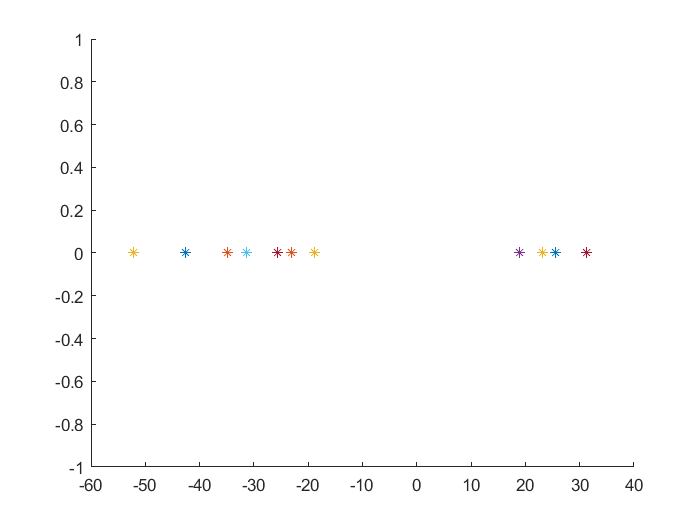



% Casos extremos de la Planta
A1 = subs(Aex, [V R L], [v1 r1 l1]); %Vmin, Rmin, Lmin
A2 = subs(Aex, [V R L], [v2 r1 l1]); %Vmax, Rmin, Lmin
A3 = subs(Aex, [V R L], [v1 r2 l1]); %Vmin, Rmax, Lmin
A4 = subs(Aex, [V R L], [v2 r2 l1]); %Vmax, Rmax, Lmin
B1 = subs(Bex, L, l1); %Lmin

A5 = subs(Aex, [V R L], [v1 r1 l2]); %Vmin, Rmin, Lmax
A6 = subs(Aex, [V R L], [v2 r1 l2]); %Vmax, Rmin, Lmax
A7 = subs(Aex, [V R L], [v1 r2 l2]); %Vmin, Rmax, Lmax
A8 = subs(Aex, [V R L], [v2 r2 l2]); %Vmax, Rmax, Lmax
B2 = subs(Bex, L, l2); %Lmax

Aall={A1, A2, A3, A4, A5, A6, A7, A8};


%Polos a lazo abierto (extremos)
figure 
hold on
for n=1:1:length(Aall)
    p=eig([[0 0; 0 0;0 0] In]*Aall{n}*[0 0 0;0 0 0; In]);
    plot(real(p(1)),imag(p(1)),'*'),
    plot(real(p(2)),imag(p(2)),'*'),
    plot(real(p(3)),imag(p(3)),'*'),
    grid 
end
hold off


fileID = fopen('orden5.txt','w');
fprintf(fileID,'%12s %12s\n','b', 'cr');


cr = pi*15/180;
Alfa=1;
Ro=500;
Theta=pi/3;


% Creación sistema LMI
setlmis([])

% Variables LMIs
S = lmivar(1,[5 1]); %simétrica, 5x5 porque Aex es de 5x5 
P = lmivar(2,[1 5]); %arbitraria, 1x5 porque B es de 1x5

% S > 0
lmiterm([-1 1 1 S],1,1);

% Restricciones asociadas al parámetro Alfa
%(A1,B1)
lmiterm([2 1 1 S],A1,1,'s');
lmiterm([2 1 1 P],B1,1,'s');
lmiterm([2 1 1 S],2*Alfa,1);
%(A2,B1)
lmiterm([3 1 1 S],A2,1,'s');
lmiterm([3 1 1 P],B1,1,'s');
lmiterm([3 1 1 S],2*Alfa,1);
%(A3,B1)
lmiterm([4 1 1 S],A3,1,'s');
lmiterm([4 1 1 P],B1,1,'s');
lmiterm([4 1 1 S],2*Alfa,1);
%(A4,B1)
lmiterm([5 1 1 S],A4,1,'s');
lmiterm([5 1 1 P],B1,1,'s');
lmiterm([5 1 1 S],2*Alfa,1);
%(A5,B2)
lmiterm([6 1 1 S],A5,1,'s');
lmiterm([6 1 1 P],B2,1,'s');
lmiterm([6 1 1 S],2*Alfa,1);
%(A6,B2)
lmiterm([7 1 1 S],A6,1,'s');
lmiterm([7 1 1 P],B2,1,'s');
lmiterm([7 1 1 S],2*Alfa,1);
%(A7,B2)
lmiterm([8 1 1 S],A7,1,'s');
lmiterm([8 1 1 P],B2,1,'s');
lmiterm([8 1 1 S],2*Alfa,1);
%(A8,B2)
lmiterm([9 1 1 S],A8,1,'s');
lmiterm([9 1 1 P],B2,1,'s');
lmiterm([9 1 1 S],2*Alfa,1);

% Restricciones asociadas al parámetro Ro
% (A1,B1)
lmiterm([10 1 1 S],-Ro,1);
lmiterm([10 1 2 S],A1,1);
lmiterm([10 1 2 P],B1,1);
lmiterm([10 2 2 S],-Ro,1);
% (A2,B1)
lmiterm([11 1 1 S],-Ro,1);
lmiterm([11 1 2 S],A2,1);
lmiterm([11 1 2 P],B1,1);
lmiterm([11 2 2 S],-Ro,1);
% (A3,B1)
lmiterm([12 1 1 S],-Ro,1);
lmiterm([12 1 2 S],A3,1);
lmiterm([12 1 2 P],B1,1);
lmiterm([12 2 2 S],-Ro,1);
% (A4,B1)
lmiterm([13 1 1 S],-Ro,1);
lmiterm([13 1 2 S],A4,1);
lmiterm([13 1 2 P],B1,1);
lmiterm([13 2 2 S],-Ro,1);
% (A1,B2)
lmiterm([14 1 1 S],-Ro,1);
lmiterm([14 1 2 S],A5,1);
lmiterm([14 1 2 P],B2,1);
lmiterm([14 2 2 S],-Ro,1);
% (A2,B2)
lmiterm([15 1 1 S],-Ro,1);
lmiterm([15 1 2 S],A6,1);
lmiterm([15 1 2 P],B2,1);
lmiterm([15 2 2 S],-Ro,1);
% (A3,B2)
lmiterm([16 1 1 S],-Ro,1);
lmiterm([16 1 2 S],A7,1);
lmiterm([16 1 2 P],B2,1);
lmiterm([16 2 2 S],-Ro,1);
% (A4,B2)
lmiterm([17 1 1 S],-Ro,1);
lmiterm([17 1 2 S],A8,1);
lmiterm([17 1 2 P],B2,1);
lmiterm([17 2 2 S],-Ro,1);

% Restricciones asociadas al parámetro Theta
% (A1, B1)
lmiterm([18 1 1 S],sin(Theta)*A1,1,'s');
lmiterm([18 1 1 P],sin(Theta)*B1,1,'s');
lmiterm([18 1 2 S],cos(Theta)*A1,1);
lmiterm([18 1 2 S],-cos(Theta),A1');
lmiterm([18 1 2 P],cos(Theta)*B1,1);
lmiterm([18 1 2 -P],-cos(Theta),B1');
lmiterm([18 2 2 S],sin(Theta)*A1,1,'s');
lmiterm([18 2 2 P],sin(Theta)*B1,1,'s');
% (A2, B1)
lmiterm([19 1 1 S],sin(Theta)*A2,1,'s');
lmiterm([19 1 1 P],sin(Theta)*B1,1,'s');
lmiterm([19 1 2 S],cos(Theta)*A2,1);
lmiterm([19 1 2 S],-cos(Theta),A2');
lmiterm([19 1 2 P],cos(Theta)*B1,1);
lmiterm([19 1 2 -P],-cos(Theta),B1');
lmiterm([19 2 2 S],sin(Theta)*A2,1,'s');
lmiterm([19 2 2 P],sin(Theta)*B1,1,'s');
% (A3, B1)
lmiterm([20 1 1 S],sin(Theta)*A3,1,'s');
lmiterm([20 1 1 P],sin(Theta)*B1,1,'s');
lmiterm([20 1 2 S],cos(Theta)*A3,1);
lmiterm([20 1 2 S],-cos(Theta),A3');
lmiterm([20 1 2 P],cos(Theta)*B1,1);
lmiterm([20 1 2 -P],-cos(Theta),B1');
lmiterm([20 2 2 S],sin(Theta)*A3,1,'s');
lmiterm([20 2 2 P],sin(Theta)*B1,1,'s');
% (A4, B1)
lmiterm([21 1 1 S],sin(Theta)*A4,1,'s');
lmiterm([21 1 1 P],sin(Theta)*B1,1,'s');
lmiterm([21 1 2 S],cos(Theta)*A4,1);
lmiterm([21 1 2 S],-cos(Theta),A4');
lmiterm([21 1 2 P],cos(Theta)*B1,1);
lmiterm([21 1 2 -P],-cos(Theta),B1');
lmiterm([21 2 2 S],sin(Theta)*A4,1,'s');
lmiterm([21 2 2 P],sin(Theta)*B1,1,'s');
% (A5, B2)
lmiterm([22 1 1 S],sin(Theta)*A5,1,'s');
lmiterm([22 1 1 P],sin(Theta)*B2,1,'s');
lmiterm([22 1 2 S],cos(Theta)*A5,1);
lmiterm([22 1 2 S],-cos(Theta),A5');
lmiterm([22 1 2 P],cos(Theta)*B2,1);
lmiterm([22 1 2 -P],-cos(Theta),B2');
lmiterm([22 2 2 S],sin(Theta)*A5,1,'s');
lmiterm([22 2 2 P],sin(Theta)*B2,1,'s');
% (A6, B2)
lmiterm([23 1 1 S],sin(Theta)*A6,1,'s');
lmiterm([23 1 1 P],sin(Theta)*B2,1,'s');
lmiterm([23 1 2 S],cos(Theta)*A6,1);
lmiterm([23 1 2 S],-cos(Theta),A6');
lmiterm([23 1 2 P],cos(Theta)*B2,1);
lmiterm([23 1 2 -P],-cos(Theta),B2');
lmiterm([23 2 2 S],sin(Theta)*A6,1,'s');
lmiterm([23 2 2 P],sin(Theta)*B2,1,'s');
% (A7, B2)
lmiterm([24 1 1 S],sin(Theta)*A7,1,'s');
lmiterm([24 1 1 P],sin(Theta)*B2,1,'s');
lmiterm([24 1 2 S],cos(Theta)*A7,1);
lmiterm([24 1 2 S],-cos(Theta),A7');
lmiterm([24 1 2 P],cos(Theta)*B2,1);
lmiterm([24 1 2 -P],-cos(Theta),B2');
lmiterm([24 2 2 S],sin(Theta)*A7,1,'s');
lmiterm([24 2 2 P],sin(Theta)*B2,1,'s');
% (A8, B2)
lmiterm([25 1 1 S],sin(Theta)*A8,1,'s');
lmiterm([25 1 1 P],sin(Theta)*B2,1,'s');
lmiterm([25 1 2 S],cos(Theta)*A8,1);
lmiterm([25 1 2 S],-cos(Theta),A8');
lmiterm([25 1 2 P],cos(Theta)*B2,1);
lmiterm([25 1 2 -P],-cos(Theta),B2');
lmiterm([25 2 2 S],sin(Theta)*A8,1,'s');
lmiterm([25 2 2 P],sin(Theta)*B2,1,'s');


% Ejecución del solver
LMISYS=getlmis;
[tmin,xfeas]=feasp(LMISYS, [0, 100, 109, 10, 0]);


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.025891
     2                    9.447269e-04
     3                    9.447269e-04
     4                    8.356358e-05
     5                    8.356358e-05
     6                    2.041756e-05
     7                    2.041756e-05
     8                    3.437625e-06
     9                    3.437625e-06
    10                    1.077742e-06
    11                    1.077742e-06
    12                    2.191761e-07
    13                    1.513979e-07
    14                    1.249067e-07
    15                    1.249067e-07
    16                    3.285755e-08
    17                    3.285755e-08
    18                    5.827598e-09
    19                    5.827598e-09
    20                    1.465699e-09
    21


if(tmin<0)
    b
    cr
    fprintf(fileID, '%f %f \n', [b cr]);
end

b = 100

cr = 0.2618


% Solución
S=dec2mat(LMISYS,xfeas,S);
P=dec2mat(LMISYS,xfeas,P);

K=P*inv(S)

K = 	1.0e+05 *

   -1.0071   -1.2375    0.8362    0.0316   -0.0028


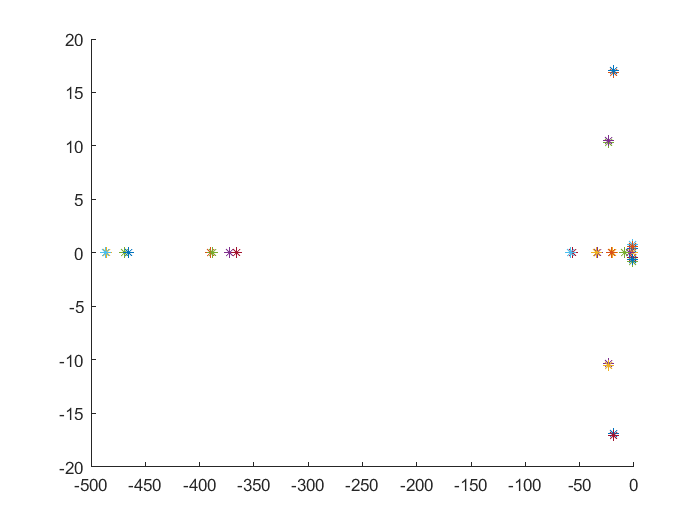




fclose(fileID);



%Polos a lazo cerrado vértices
figure 
hold on
for n=1:1:length(Aall)
    if n < 5
        p=eig(Aall{n}+B1*K);
    end
    if n > 4
        p=eig(Aall{n}+B2*K);
    end
    plot(real(p(1)),imag(p(1)),'*'),plot(real(p(2)),imag(p(2)),'*'),
    plot(real(p(3)),imag(p(3)),'*'),plot(real(p(4)),imag(p(4)),'*'),
    plot(real(p(5)),imag(p(5)),'*')
    grid  
end
hold off